# Identification of Discrete Time Dynamic System Models

## Introduction

Identification of the half quad rotor model

## Load data

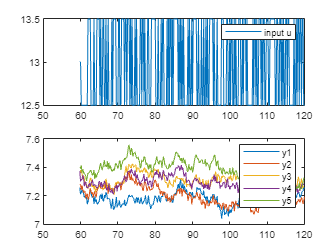

%% Load and print 5 sets of identification data
load('data_ident_prbs1.mat');
u1=out.signals.values(300:end,6);
y1=out.signals.values(300:end,3);
t1=out.time(300:end);
load('data_ident_prbs2.mat');
u2=out.signals.values(300:end,6);
y2=out.signals.values(300:end,3);
t2=out.time(300:end);
load('data_ident_prbs3.mat');
u3=out.signals.values(300:end,6);
y3=out.signals.values(300:end,3);
t3=out.time(300:end);
load('data_ident_prbs4.mat');
u4=out.signals.values(300:end,6);
y4=out.signals.values(300:end,3);
t4=out.time(300:end);
load('data_ident_prbs5.mat');
u5=out.signals.values(300:end,6);
y5=out.signals.values(300:end,3);
t5=out.time(300:end);
clf;
subplot(211);h1=plot(t1,u1);legend('input u');
subplot(212);h2=plot(t1,y1,t2,y2,t3,y3,t4,y4,t5,y5);legend('y1','y2','y3','y4','y5');

Preprocess Data

%% Data pre-processing
%Select data
u=u1;
y=y1';
%remove mean
y = y-mean(y);
u = u - mean(u);
%split data (ident and validation)
split = 290;
yid=y(1:split)-mean(y(1:split));
uid=u(1:split)-mean(u(1:split));
yvalid = y(split:end)-mean(y(split:end));
uvalid = u(split:end)-mean(u(split:end));

## Identify models

### Dimension and structure choice

na = 1;
nb = 1;
nc = 1;

### Find model

[A1,B1] = RLS(uid,yid,na,nb);

     1

   -0.0631
    0.0310

     2

   -0.0174
    0.0310

     3

   -0.0317
   -0.4690

     4

   -0.0466
   -0.4690

     5

   -0.0366
   -0.4690

     6

   -0.0194
   -0.4690

     7

   -0.0003
   -0.4690

     8

    0.0054
   -0.4690

     9

    0.0108
   -0.4690

    10

    0.0011
   -0.4690

    11

    0.0530
   -0.4690

    12

    0.0339
    0.5310

    13

    0.0115
    0.5310

    14

   -0.0255
    0.5310

    15

   -0.0408
    0.5310

    16

   -0.0298
   -0.4690

    17

    0.0003
   -0.4690

    18

    0.0056
   -0.4690

    19

    0.0011
   -0.4690

    20

    0.0507
    0.5310

    21

   -0.0024
   -0.4690

    22

    0.0357
   -0.4690

    23

    0.0186
   -0.4690

    24

    0.0511
    0.5310

    25

    0.0501
    0.5310

    26

    0.0397
    0.5310

    27

    0.0334
    0.5310

    28

   -0.0060
   -0.4690

    29

   -0.0151
    0.5310

    30

    0.0163
   -0.4690

    31

   -0.0223
   -0.4690

    32

    0.0299
    0.5310

    33



%[A2,B2,C2] = ELS(uid,yid,na,nb,nc);

## Validate and compare models

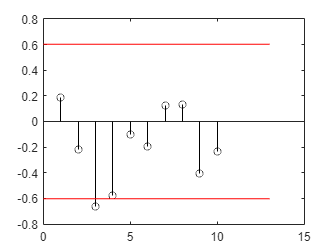

[err1,J,AIC] = computerrors(uvalid,yvalid,A1,B1,na,nb);
N = length(uvalid);
RN = xcorr(err1);
R0 = RN(N);
RN = RN/R0;
clf;
stem(RN(N+1:end),'k');
hold on;
line([0 N],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([0 N],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

## Time domain simulation

num = [0 B1'];
den = [1 A1'];
sys1 = tf(num,den,1,'variable','z^-1');
num = [0 B2'];
den = [1 A2'];
sys2 = tf(num,den,1,'variable','z^-1');
clf
step(sys1,sys2);legend('rls','els');

## Functions

### Recursive Least Square

function [A,B] = RLS(uid,yid,na,nb)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%
c = 1;
theta_past = zeros(na+nb,1);                     % column vector
D_past = c*eye(na+nb,na+nb);                      % square vector
for t = (max(na,nb)):length(uid)-1          % iteration goes till 49 since the 50th value is used in epsilon
    disp(t)
    phi = [-yid(t:-1:t-na+1) ; uid(t:-1:t-nb+1)];    % required number of values in order of chronology are taken
    disp(phi)
    epsilon = yid(t+1) - phi'*theta_past;               % scalar

    D = D_past - (D_past*phi*phi'*D_past)/(1+phi'*D_past*phi);       % square matrix (na+nb,na+nb)
    theta = theta_past + ((D_past*phi)/(1+phi'*D_past*phi))*epsilon;

    theta_past = theta;
    D_past = D;
end
A = theta(1:na);
B = theta(na+1:na+nb);
end

### Recursive Extended Least Square

%function [A,B,C] = ELS(uid,yid,na,nb,nc)
%uid = reshape(uid,[],1);
%yid = reshape(yid,[],1);
%
%
%end

### Prediction Error and AIC criteria

function [err, J, AIC] = computerrors(uvalid,yvalid,A,B,na,nb)
uvalid = reshape(uvalid,[],1);
yvalid = reshape(yvalid,[],1);
theta = [A;B];
J = 0;
err=[];
for t=max(na,nb):length(yvalid)-1
    phi = [-yvalid(t:-1:t-na+1) ; uvalid(t:-1:t-nb+1)];
    err(end+1) = yvalid(t+1) - phi'*theta;
    J = J + (yvalid(t+1) - phi'*theta)^2;
end
AIC=2*((na+nb)/length(yvalid)) + (log(J)^(na+nb));
end